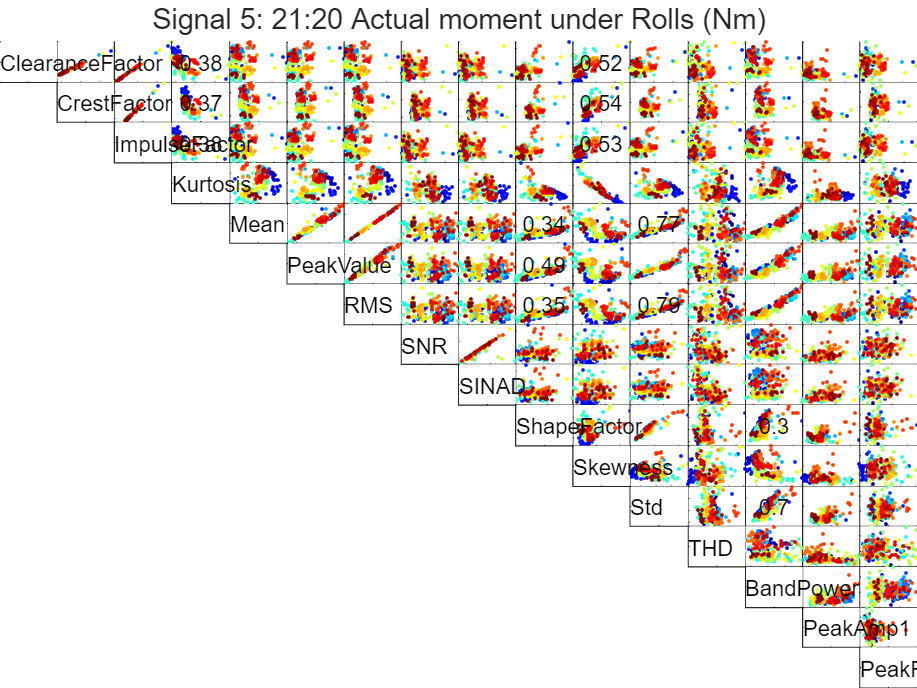

Features = DFD_FeatureTable_TimeDomain;
SignalNames = signalNames_Time;
FeatureNames = featureNames_Time;
lowerR2 = 0.3;
upperR2 = 0.8;
signalNum = 5;
R2 = fnPlotFeatureVsFeature_Array(featureArray, lowerR2, upperR2, signalNum, combinedFeatureNames, sensorNames);

disp(num2str(R2, '%.2f  '));

0.00  0.98  1.00  0.38  0.02  0.01  0.02  0.03  0.01  0.25  0.52  0.04  0.05  0.02  0.00  0.00
0.00  0.00  0.99  0.37  0.05  0.00  0.05  0.03  0.00  0.15  0.54  0.01  0.05  0.05  0.01  0.00
0.00  0.00  0.00  0.38  0.03  0.00  0.03  0.03  0.00  0.21  0.53  0.03  0.05  0.03  0.00  0.00
0.00  0.00  0.00  0.00  0.17  0.07  0.16  0.06  0.02  0.12  0.91  0.00  0.06  0.16  0.00  0.00
0.00  0.00  0.00  0.00  0.00  0.95  1.00  0.01  0.00  0.34  0.28  0.77  0.05  0.90  0.13  0.02
0.00  0.00  0.00  0.00  0.00  0.00  0.95  0.00  0.00  0.49  0.13  0.87  0.03  0.85  0.13  0.02
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.01  0.00  0.35  0.27  0.79  0.05  0.90  0.14  0.02
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.87  0.02  0.05  0.00  0.02  0.01  0.10  0.01
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.01  0.01  0.00  0.11  0.00  0.10  0.01
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.06  0.80  0.01  0.30  0.17  0.01
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.

fs = 1 / Ts; % Sampling frequency
selectedFeature = 1;
selectedFeatureArray = [selectedFeature]; % Array of correlated features
for i = 1:numOfCombinedFeatures + 1 - selectedFeature
    if R2(i,selectedFeature) > lowerR2 && R2(i,selectedFeature) < upperR2
        selectedFeatureArray = [selectedFeatureArray i];
    end
end
for i = selectedFeature + 1:numOfCombinedFeatures
    if R2(selectedFeature,i) > lowerR2 && R2(selectedFeature,i) < upperR2
        selectedFeatureArray = [selectedFeatureArray i];
    end
end
selectedFeatureArray = sort(selectedFeatureArray);
numOfSelectedFeatures = size(selectedFeatureArray, 2);
selectedFeatureData = {numOfSelectedFeatures};

for i = 1:numOfSelectedFeatures
    selectedFeatureData{i} = featureArray(:, i, signalNum);
end

disp(selectedFeatureArray);

     1     4    11



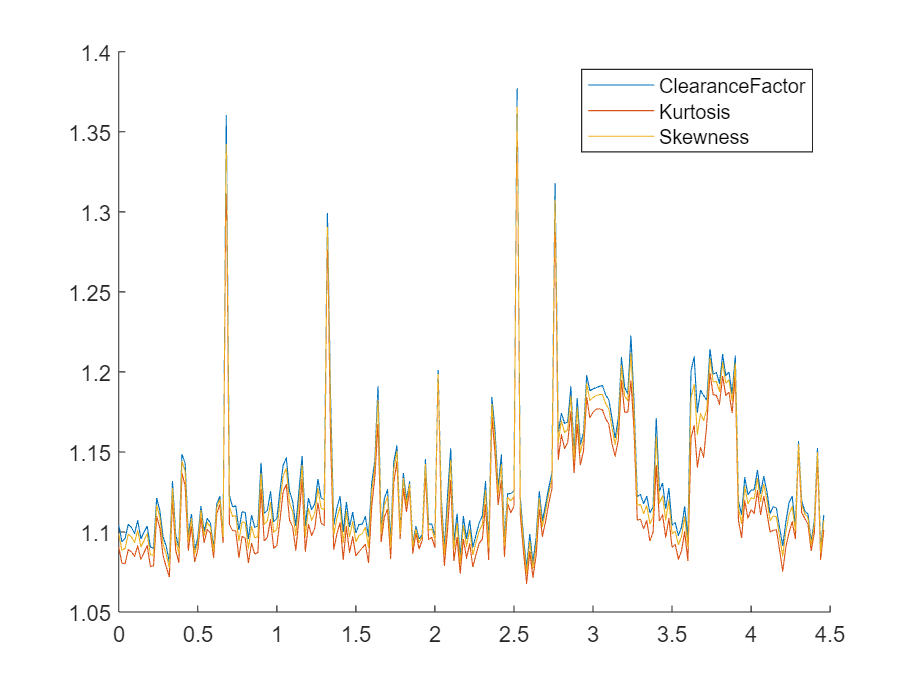

% Plot the identified signals for the Mean of each signal
n = size(selectedFeatureData{1}, 1); % Sample , 10
t = ( 0 : 1/fs : (n / fs) - 1/fs)';
figure(); hold on;
leg = {numOfSelectedFeatures};
for signalIndex = 1:numOfSelectedFeatures
    plot(t, selectedFeatureData{signalIndex});
    txtTemp = char(combinedFeatureNames(selectedFeatureArray(signalIndex)));
    leg{signalIndex} = char(txtTemp);
end
legend(leg);

X_signals = zeros(n, numOfSelectedFeatures);
for index = 1:numOfSelectedFeatures
    X_signals(:,index) = selectedFeatureData{index}; 
end

X1 = X_signals(:,1);
X2 = X_signals(:,2);
X3 = X_signals(:,3);
% X4 = X_signals(:,4);
% X5 = X_signals(:,5);
% X6 = X_signals(:,6);

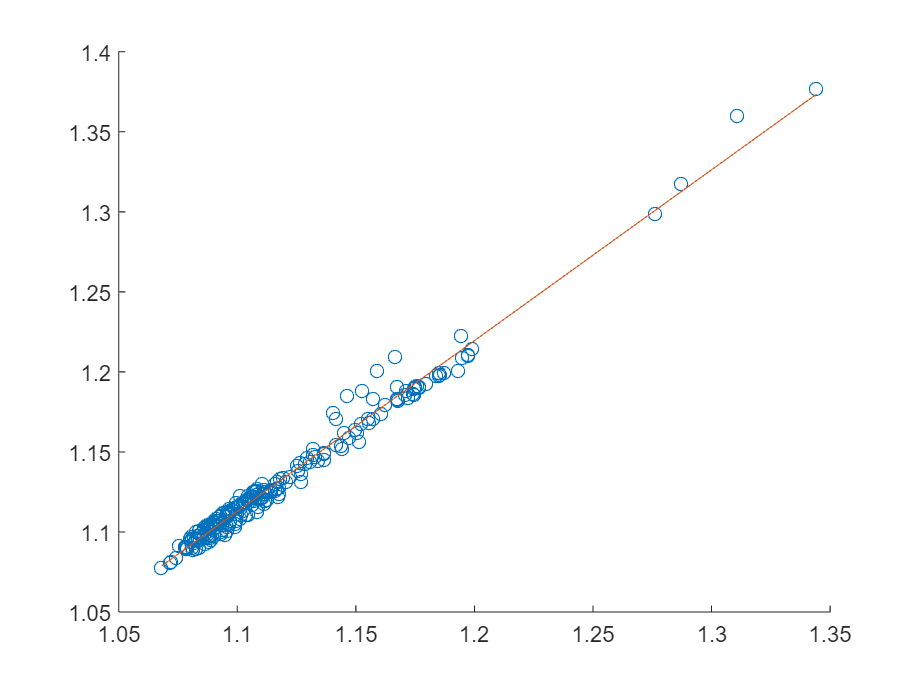

FIT = 87.207726

fnPlotModel(X1, X2);

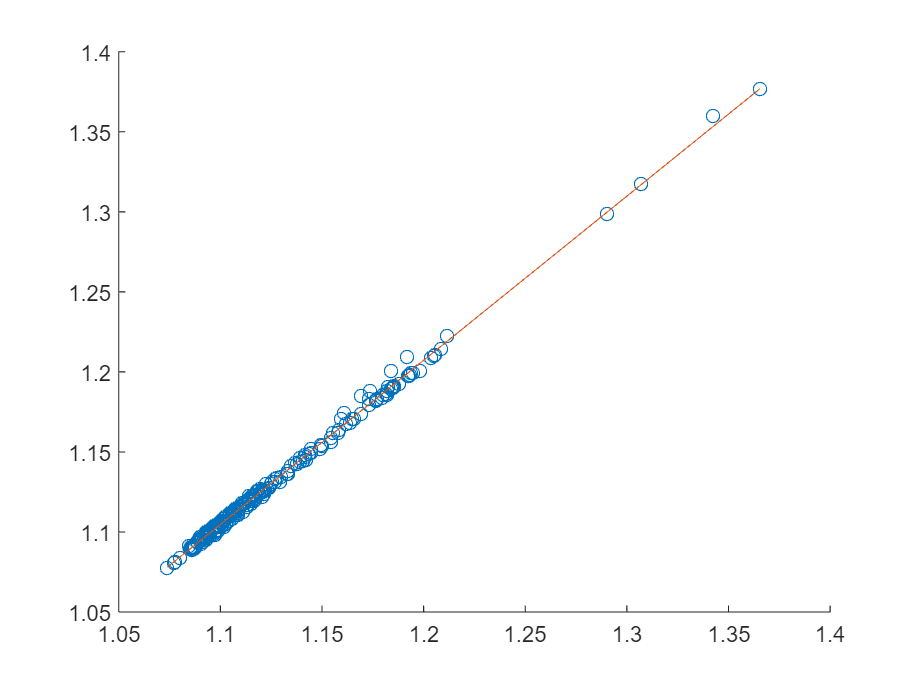

FIT = 94.950497

fnPlotModel(X1, X3);

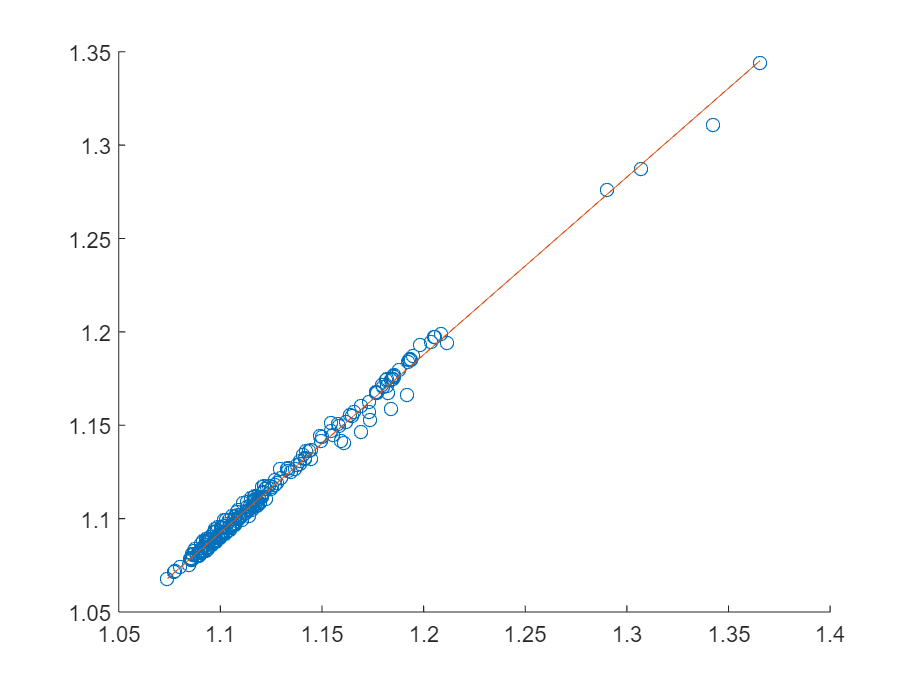

FIT = 92.210630

fnPlotModel(X2, X3);